# Atomically resolve a metabolic reconstruction

## Author: German Preciat, Analytical BioSciences, Leiden University

## INTRODUCTION

Genome-scale metabolic network reconstructions have become a relevant tool in modern biology to study the metabolic pathways of biological systems *in silico*. However, a more detailed representation at the underlying level of atom mappings opens the possibility for a broader range of biological, biomedical and biotechnological applications than with stoichiometry alone.

This tutorial will demonstrate how to use the chimoinformatic tools in the COBRA Toolbox. The tutorial is divided into three sections: first, the chimoinformatic data of the metabolites in a COBRA model is processed generating metabolite structures in various chemoinfomatic formats; second, the atoms of their reactions are mapped; and finally, all of the tools demonstrated are used to generate a standardized chemoinformatic database specific to the COBRA model. The chemoinformatic database will be generated using information from the ecoliCore model.

## MATERIALS

To atom map reactions it is required to have Java version 8 and Linux. The atom mapping does not run on Windows at present. 

On *macOS*, please make sure that you run the following commands in the Terminal before continuing with this tutorial:

`$ /usr/bin/ruby -e "$(curl -fsSL` [`https://raw.githubusercontent.com/Homebrew/install/master/install`](https://raw.githubusercontent.com/Homebrew/install/master/install)`)"`

`$ brew install coreutils`

`On` `Linux`, please make sure that Java and ChemAxon directories are included. To do this, run the following commands:

`$ export PATH=$PATH:/opt/opt/chemaxon/jchemsuite/bin/` (default location of JChem)

`$ export PATH=$PATH:/usr/java/jre1.8.0_131/bin/` (default installation of Java)

Also, in order to standardise the chemical reaction format, it is required to have JChem downloaded from ChemAxon with its respective license.

## Metabolites

Metabolite structures are represented in a variety of chemoinformatic formats, including 1) Metabolite chemical tables (MDL MOL) that list all of the atoms in a molecule, as well as their coordinates and bonds${\;}^1$; 2) The simplified molecular-input line-entry system (SMILES), which uses a string of ASCII characters to describe the structure of a molecule${\;}^2$; or 3) The International Chemical Identifier (InChI) developed by the IUPAC, provides a standard representation for encoding molecular structures using multiple layers to describe a metabolite structure${\;}^3$ (see Figure 1). Additionally, different chemical databases assing a particular identifier to represent the metabolite structures as the Virtual Metabolic Human database (**VMH**)${\;}^4$, the Human Metabolome Database (**HMDB**)${\;}^5$, **PubChem** database${\;}^6$, the Kyoto Encyclopedia of Genes and Genomes(**KEEG**)${\;}^7$, and the Chemical Entities of Biological Interest (**ChEBI**)${\;}^8$. 

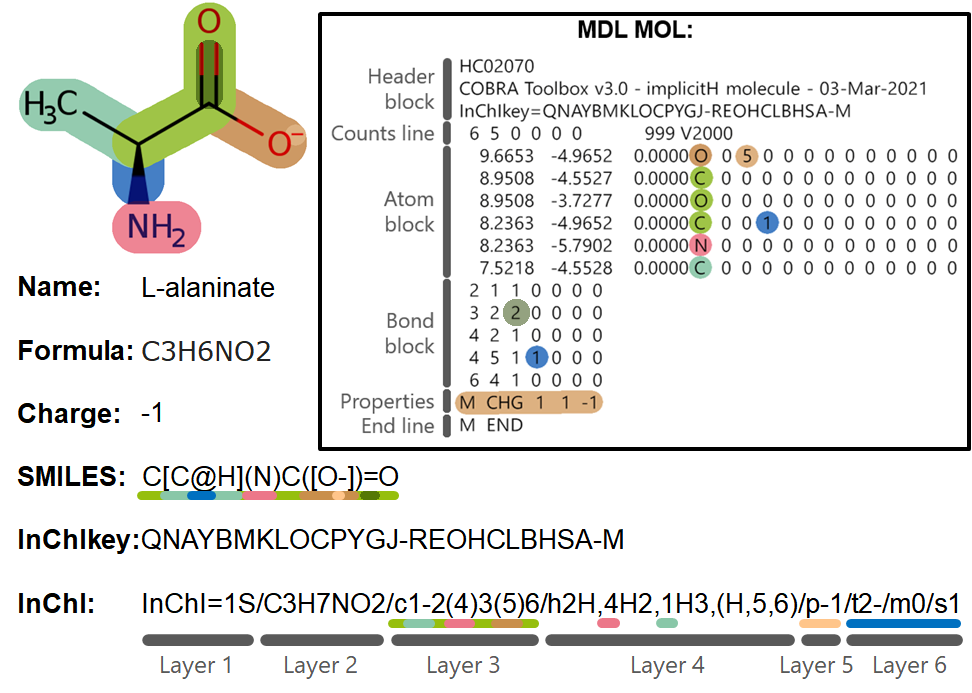

Figure 1. L-alaninate molecule represented by a hydrogen-suppressed molecular graph (implicit hydrogens). The main branch of the molecule can be seen in green; the additional branches can be seen in brown, pink and turquoise. The stereochemistry of the molecule is highlighted in blue, the double bond with dark green and the charges are highlighted in light brown. The same colours are used to indicate where this information is represented in the different chemoinformatic formats. The InChI is divided into layers, each of which begins with a lowercase letter, except for Layers 1 and 2. Layer 1 indicates if the InChI is standardised, Layer 2 the chemical formula in a neutral state, Layer 3 the connectivity between the atoms (ignoring hydrogen atoms), Layer 4 the connectivity of hydrogen atoms, Layer 5 the charge of the molecule and Layer 6 the stereochemistry. Additional layers can be added, but they cannot be represented with a standard InChI.

First we clean the workspace and load the model.

clear
load ecoli_core_model.mat
model.mets = regexprep(model.mets, '\-', '\_');

### Add metabolite information

The `addMetInfoInCBmodel` function will be used to add the identifiers. The chemoinformatic data is obtained from an external file and is added to the ecoliCore model. The chemoinformatic information includes SMILES, InChIs, or different database identifiers.

dataFile = which('chemoinformaticDatabaseTutorial.mlx');
inputData = regexprep(dataFile, 'chemoinformaticDatabaseTutorial.mlx', 'metaboliteIds.xlsx');
replace = false;
[model, hasEffect] = addMetInfoInCBmodel(model, inputData, replace);
clearvars -except model

### Download metabolites from model identifiers

The `obtainMetStructures` function is used to obtain MDL MOL files from different databases, including HMDB${\;}^5$, PubChem${\;}^6$, KEEG${\;}^7$ and ChEBI${\;}^8$. Alternatively, the function can be used to convert the InChI strings or SMILES in the model to MDL MOL files. A COBRA model with identifiers is required to run the function.

The optional variables are:

The variable |mets| contains a list of metabolites to be download (Default: All). To obtain the metabolite structure of glucose, we use the VMH id.

mets = {'2pg'; 'h2o'; 'pep'; 'fdp'; 'f6p'; 'pi'};

`outputDir`: Path to the directory that will contain the MOL files (default: current directory).

outputDir = [pwd filesep 'comparison' filesep];

`sources`, is an array indicating the source of preference (default: all the sources with ID)

- InChI (requires openBabel)

- Smiles (requires openBabel)

- KEGG ([https://www.genome.jp/](https://www.genome.jp/))

- HMDB ([https://hmdb.ca/](https://hmdb.ca/))

- PubChem ([https://pubchem.ncbi.nlm.nih.gov/](https://pubchem.ncbi.nlm.nih.gov/))

- CHEBI ([https://www.ebi.ac.uk/](https://www.ebi.ac.uk/))

sources = {'inchi'; 'smiles'; 'kegg'; 'hmdb'; 'pubchem'; 'chebi'};

Run the function

molCollectionReport = obtainMetStructures(model, mets, outputDir, sources);

### Convert metabolites

Open Babel${\;}^9$ is a chemical toolbox designed to translate the different chemical data languages. It is possible to convert between chemical formats such as MDL MOL files to InChI. This function `openBabelConverter` converts chemoformatic formats using OpenBabel. It requires having OpenBabel installed. 

The function requires the original chemoinformatic structure (`origFormat`) and the output format (`outputFormat`). The formats supported are SMILES, MD MOL, InChI, InChIKey, rxn and rinchi. Furthermore, if the optional variable `saveFileDir` is set, the new format will be saved with the name specified in the variable.

All of the downloaded metabolite structures are converted to an InChI as follows.

[inchis, smiles] = deal(cell(size(mets)));
for i = 1:length(sources)
    metaboliteDir = [outputDir 'metabolites' filesep sources{i} filesep];
    inchis{i, 1} = openBabelConverter([metaboliteDir 'f6p.mol'], 'inchi');
    smiles{i, 1} = openBabelConverter(inchis{i, 1}, 'smiles');
end
table(mets, inchis, smiles)

ans = 6×3 table
     mets                                                           inchis                                                                                smiles                       
    _______    _________________________________________________________________________________________________________________    ___________________________________________________

    {'2pg'}    {'InChI=1S/C6H13O9P/c7-2-6(10)5(9)4(8)3(15-6)1-14-16(11,12)13/h3-5,7-10H,1-2H2,(H2,11,12,13)/p-2'               }    {'C(C1C(C(C(CO)(O)O1)O)O)OP(=O)([O-])[O-]'        }
    {'h2o'}    {'InChI=1S/C6H13O9P/c7-2-6(10)5(9)4(8)3(15-6)1-14-16(11,12)13/h3-5,7-10H,1-2H2,(H2,11,12,13)/p-2'               }    {'C(C1C(C(C(CO)(O)O1)O)O)OP(=O)([O-])[O-]'        }
    {'pep'}    {'InChI=1S/C6H13O9P/c7-2-6(10)5(9)4(8)3(15-6)1-14-16(11,12)13/h3-5,7-10H,1-2H2,(H2,11,12,13)/t3-,4-,5+,6?/m1/s1'}    {'C([C@@H]1[C

### InChI comparison

With the function `compareInchis`, each InChI string is given a score based on its similarity to the chemical formula and charge of the metabolite in the model. Factors such as stereochemistry, if it is a standard inchi, and its similarity to the other inchis are also considered. The InChI with the highest score is the identifier considered as more consistent with the model.

comparisonTable = compareInchis(model, inchis, 'f6p');
display(comparisonTable)

comparisonTable = 6×15 table
    scores    rGroup                                                          InChI                                                          metFormula    formulaOkBool    netCharge    chargeOkBool    stereochemicalSubLayers    standard    sourceSimilarity    mainLayerSimilarity    isotopicLayer    layers    inchiWithMoreLayers                                             mainLayer                                          
    ______    ______    _________________________________________________________________________________________________________________    __________    _____________    _________    

### Metabolite structure standardisation

- explicitH: Chemical graphs; 

- implicitH: Hydrogen suppressed chemical graph; 

- basic: Update the header. 

hmdbDir = [outputDir 'metabolites' filesep 'hmdb' filesep];
metList = mets;
standardisedDir = [pwd filesep 'mets' filesep];
standardisationApproach = 'explicitH';
standardisationReport = standardiseMolDatabase(hmdbDir, metList, ...
    standardisedDir, standardisationApproach);


 Standardizing 6 MOL files ... 


### Metabolite structures

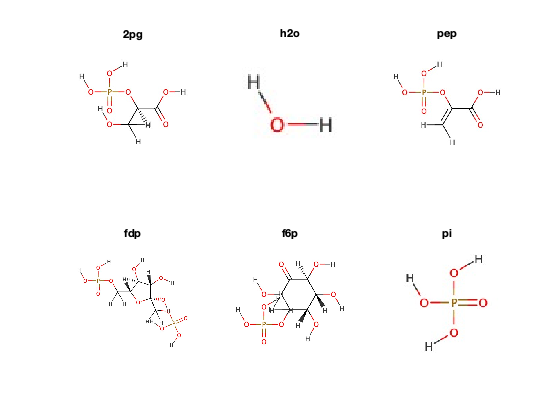

imagesFolder = [standardisedDir 'images' filesep];
figure
for i = 1:length(metList)
    subplot(2, 3, i)
    imshow([imagesFolder metList{i} '.jpeg'])
    title(metList{i})
end

## Reactions

A set of atom mappings represents the mechanism of each chemical reaction in a metabolic network, each of which relates an atom in a substrate metabolite to an atom of the same element in a product metabolite (Figure 1). To atom map reactions in a metabolic network reconstruction, one requires chemical structures in a data file format (SMILES, MDL MOL, InChIs), reaction stoichiometries, and an atom mapping algorithm.

A set of atom mappings represents the mechanism of each chemical reaction in a metabolic network, each of which relates an atom in a substrate metabolite to an atom of the same element in a product metabolite (Figure 1). To atom map reactions in a metabolic network reconstruction, one requires chemical structures in a data file format (SMILES, MDL MOL and InChIs), reaction stoichiometries, and an atom mapping algorithm.

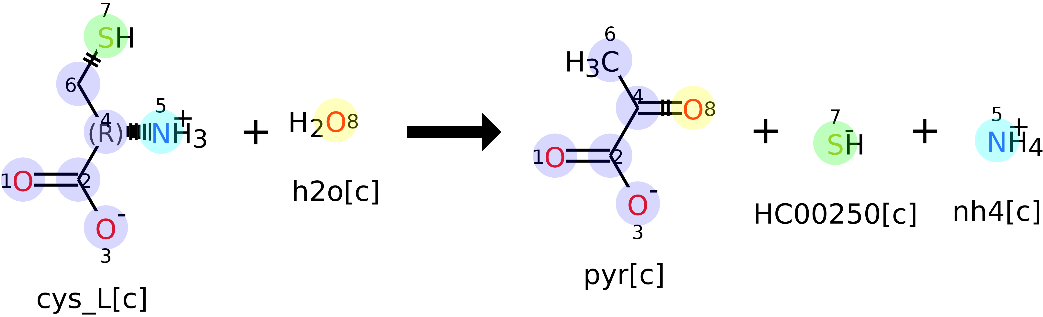

Figure 1. Set of atom mappings for reaction L-Cysteine L-Homocysteine-Lyase (VMH ID: r0193).

Metabolite structures and reaction stoichiometries from the genome-scale reconstruction are used to generate reaction chemical tables containing information about the chemical reactions (MDL RXN). The metabolic reactions are atom mapped using the Reaction Decoder Tool (RDT) algorithm${\;}^{11}$, which was chosen after comparing the performance of published atom mapping algorithms${\;}^{12}$. Atom map metabolic reactions Atom mappings for the internal reactions of a metabolic network reconstruction are performed by the function `obtainAtomMappingsRDT`. 

For this section, the atom mappings are generated based on the molecular structures obtained and the ecoli core model. 

The function `obtainAtomMappingsRDT` generates 4 different directories containing: 

- the atom mapped reactions in MDL RXN format (directory *atomMapped*), 

- the images of the atom mapped reactions (directory *images*), 

- additional data for the atom mapped reactions (SMILES, and product and reactant indexes) (directory *txtData*), and 

- the unmapped MDL RXN files (directory *rxnFiles*). 

The input variable `outputDir` indicates the directory where the folders will be generated (by default the function assigns the current directory).

## Atom map a reaction

The main inputs of the `obtainAtomMappingsRDT function `are a COBRA model structure and a directory containing the molecular structures in MDL MOL format. The variable `molFileDir `contains the path to the directory containing MOL files of the COBRA model. 

molFileDir = [standardisedDir filesep 'molFiles'];

The variable `rxnDir` specifies the path to the directory containing the RXN files with atom mappings.

rxnDir = [pwd filesep 'rxns'];

The input variable `rxnsToAM` indicates the reactions that will be atom mapped. By default the function atom map all the internal reactions with all of its metabolites present in the metabolite database (`molFileDir`).

rxnsToAM = {'ENO'; 'FBP'};

The variable `hMapping`, indicates if the hydrogen atoms will be also atom mapped (Default: `true`).

hMapping = true;

Finally, the variable `onlyUnmapped` indicates if only the reaction files will be generated without atom mappings (Default: `false`).

onlyUnmapped = false;

Now, let's obtain the atom map using `obtainAtomMappingsRDT`: 

atomMappingReport = obtainAtomMappingsRDT(model, molFileDir, rxnDir, rxnsToAM, hMapping, onlyUnmapped);



Generating RXN files.
Computing atom mappings for 2 reactions.



The output, `atomMappingReport,` contains a report of the reactions written which include:

- `rxnFilesWritten`: The MDL RXN written.

- `balanced`: The atomically balanced reactions.

- `unbalanced`: The atomically unbalanced reactions.

- mapped: The atom mapped reactions.

- `notMapped:` The unmapped reactions.

- `inconsistentBool`: A Boolean vector indicating the inconsistent reactions.

- `rinchi`: The reaction InChI for the MDL RXN files written.

- `rsmi`: The reaction SMILES for the MDL RXN files written.

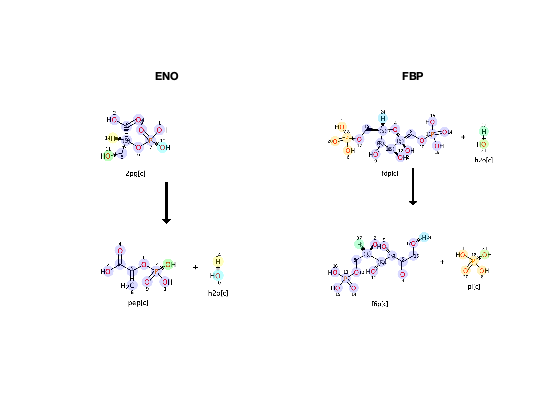

imagesFolder = [rxnDir filesep 'images' filesep];
figure
for i = 1:length(rxnsToAM)
    subplot(1, 2, i)
    imshow([imagesFolder rxnsToAM{i} '.png'])
    title(rxnsToAM{i})
end

### Read atom mapping data

The information of an atom mapped reaction is extracted using the function `readAtomMappingFromRxnFile`, which includes a metabolite identifier, the element, the atom mapping index, the identification of substrate or product, and a vector indicating which instance of a repeated metabolite atom I belongs to. The atom mapped data for the reaction enolase is extracted in the following example.

atomMapDir = [rxnDir filesep 'atomMapped'];
[mets, elements, metNrs, rxnNrs, isSubstrate, instances] = readAtomMappingFromRxnFile('ENO', atomMapDir);
display(table(mets, elements, metNrs, rxnNrs, isSubstrate, instances))

  36×6 table

       mets       elements    metNrs    rxnNrs    isSubstrate    instances
    __________    ________    ______    ______    ___________    _________

    {'2pg[c]'}     {'H'}         1         1         true            1    
    {'2pg[c]'}     {'O'}         2         2         true            1    
    {'2pg[c]'}     {'C'}         3         3         true            1    
    {'2pg[c]'}     {'O'}         4         4         true            1    
    {'2pg[c]'}     {'C'}         5         5         true            1    
    {'2pg[c]'}     {'H'}         6         6         true            1    
    {'2pg[c]'}     {'O'}         7         7         true            1    
    {'2pg[c]'}     {'P'}         8         8

### Find the enthalpy change and number of bonds broken and formed

The `findEnthalpyChange` and `findBondsBrokenAndFormed` functions are used to calculate the enthalpy change or the number of broken and formed bonds of each reaction in list `rxnsToAM` using the reaction mechanism identified by the atom mapping. Furthermore, the total weight of all substrates is calculated by adding the atomic weight of each atom.

[enthalpyChange, substrateMass] = findEnthalpyChange(model, rxnsToAM, atomMapDir);
[bondsBrokenAndFormed, ~] = findBondsBrokenAndFormed(model, rxnsToAM, atomMapDir);

Make a table of enthalpy change, bonds broken and formed, and sort it by modified bonds.

rxnDataTable = table(rxnsToAM, bondsBrokenAndFormed, enthalpyChange, substrateMass, ...
    'VariableNames', {'rxns','bondsBrokenAndFormed', 'enthalpyChange', 'substrateMass'});
rxnDataTable = sortrows(rxnDataTable, {'bondsBrokenAndFormed'}, {'descend'});
display(rxnDataTable)

rxnDataTable = 2×4 table
     rxns      bondsBrokenAndFormed    enthalpyChange    substrateMass
    _______    ____________________    ______________    _____________

    {'FBP'}             8                   -83             358.13    
    {'ENO'}             6                    54             186.06    


## Chemoinformatic database

The function `generateChemicalDatabase` generates a chemoinformatic database of standardised metabolite structures and atom-mapped reactions on a genome-scale metabolic reconstruction using the tools described in this tutorial. In order to identify the metabolite structure that most closely resembles the metabolite in the genome-scale reconstruction, identifiers from different sources are compared based on their InChI (See Table 1). Finally, the obtained atom mapped reactions are used to identify the number of broken and formed bonds, as well as the enthalpy change of the reactions in the genome-scale reconstruction.

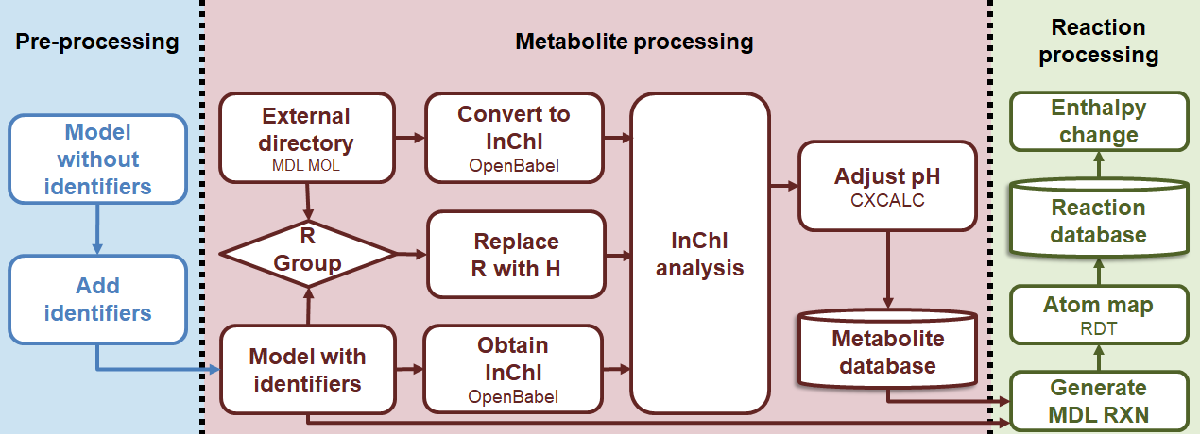

Figure 2. `generateChemicalDatabase` workflow

Table 1. InChI scoring criteria.

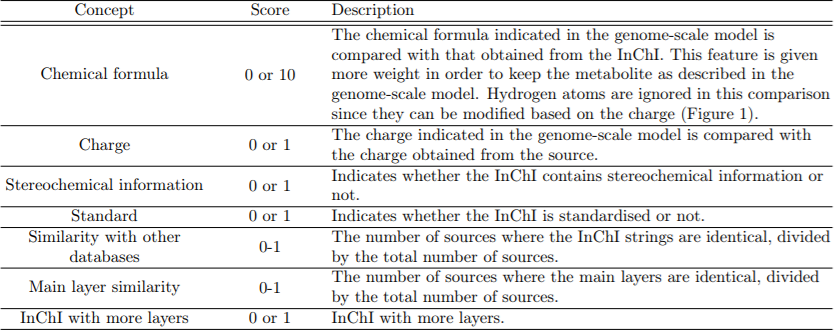

The goal of the comparison is to obtain a larger number of atomically balanced metabolic reactions. The Reaction Decoder Tool algorithm${\;}^8$ (**RDT**) is used to obtain the atom mappings of each metabolic reaction. The atom mapping data is used to calculate the number of bonds formed or broken in a metabolic reaction, as well as the enthalpy change. The information gathered is incorporated into the COBRA model.

We will obtain chemoinformatic database of the Ecoli core model in this tutorial. 

The user-defined parameters in the function `generateChemicalDatabase` will activate various processes. Each parameter is contained in the struct array  `options` and described in detail below:

- **outputDir**: The path to the directory containing the chemoinformatic database (default: current directory)

- **printlevel**: Verbose level 

- **standardisationApproach**: String containing the type of standardisation for the molecules (default: 'explicitH' if openBabel${\;}^9$ is installed, otherwise default: 'basic'):

- explicitH: Chemical graphs; 

- implicitH: Hydrogen suppressed chemical graph; 

- basic: Update the header. 

- **keepMolComparison**: Logical value, indicate if all metabolite structures per source will be saved or not.

- **onlyUnmapped**: Logic value to select create only unmapped MDL RXN files (default: FALSE, requires Java to run the RDT${\;}^{11}$). 

- **adjustToModelpH**: Logic value used to determine whether a molecule's pH must be adjusted in accordance with the COBRA model. (default: TRUE, requires MarvinSuite${\;}^{10}$). 

- **addDirsToCompare**: Cell(s) with the path to directory to an existing database (default: empty).

- **dirNames**: Cell(s) with the name of the directory(ies) (default: empty).

- **debug**: Logical value used to determine whether or not the results of different points in the function will be saved for debugging (default: empty).

options.outputDir = [pwd filesep 'database'];
options.printlevel = 1;
options.debug = true;
options.standardisationApproach = 'explicitH';
options.adjustToModelpH = true;
options.keepMolComparison = false;
options.dirsToCompare = {['~' filesep 'work' filesep 'code' filesep 'ctf' filesep 'mets' filesep 'molFiles']};
options.onlyUnmapped = false;
options.dirNames = {'VMH'};

Use the function `generateChemicalDatabase`

--------------------------------------------------------------
CHEMICAL DATABASE
--------------------------------------------------------------
 
Generating a chemical database with the following options:
 
                  outputDir: '/Users/gpreciat/Desktop/asd/database'
                 printlevel: 1
                      debug: 1
    standardisationApproach: 'explicitH'
            adjustToModelpH: 1
          keepMolComparison: 0
              dirsToCompare: {'~/work/code/ctf/mets/molFiles/'}
               onlyUnmapped: 0
                   dirNames: {'VMH'}

--------------------------------------------------------------
Obtaining MOL files from chemical databases ...

inchi:


molCollectionReport = struct with fields:
              mets: {54×1 cell}
       metsWithMol: {50×1 cell}
    metsWithoutMol: {4×1 cell}
          coverage: 92.5926
        idsToCheck: {}


smiles:


molCollectionReport = struct with fields:
              mets: {54×1 cell}
       metsWithMol: {50×1 cell}
    metsWithoutMol: {4×1 cell}
          coverage: 92.5926
        idsToCheck: {}


kegg:


molCollectionReport = struct with fields:
              mets: {54×1 cell}
       metsWithMol: {31×1 cell}
    metsWithoutMol: {23×1 cell}
          coverage: 57.4074
        idsToCheck: {}


The server returned the status 503 with message "Service Temporarily Unavailable" in response to the request to URL https://hmdb.ca/structures/metabolites/HMDB0000217.mol.
The server returned the status 503 with message "Service Temporarily Unavailable" in response to the request to URL https://hmdb.ca/structures/metabolites/HMDB0000051.mol.
The server returned the status 503 with message "Service Temporarily Unavailable" in response to the request to URL https://hmdb.ca/structures/metabolites/HMDB0001377.mol.
The server returned the status 503 with message "Service Temporarily Unavailable" in response to the request to URL https://hmdb.ca/structures/metabolites/HMDB0000263.mol.
The server returned the status 503 with message "Service Temporarily Unavailable" in response to the request to URL https://hmdb.ca/structures/metabolites/HMDB0001429.mol.
The server returned the status 503 with message "Service Temporarily Unavailable" in response to the request to URL https://hmdb.ca/structur

molCollectionReport = struct with fields:
              mets: {54×1 cell}
       metsWithMol: {40×1 cell}
    metsWithoutMol: {14×1 cell}
          coverage: 74.0741
        idsToCheck: {11×1 cell}


pubchem:


molCollectionReport = struct with fields:
              mets: {54×1 cell}
       metsWithMol: {50×1 cell}
    metsWithoutMol: {4×1 cell}
          coverage: 92.5926
        idsToCheck: {}


chebi:


molCollectionReport = struct with fields:
              mets: {54×1 cell}
       metsWithMol: {48×1 cell}
    metsWithoutMol: {6×1 cell}
          coverage: 88.8889
        idsToCheck: {}


VMH:
  struct with fields:

              mets: {54×1 cell}
       metsWithMol: {53×1 cell}
    metsWithoutMol: {'acon_C'}
          coverage: 98.1481

Comparing information from sources ...
  53×6 table

       mets                       source                     score                                                                                                                                                                        inchi                                                                                                                                                                        chargeOkBool       metFormula   
    __________    _______________________________________    ______    

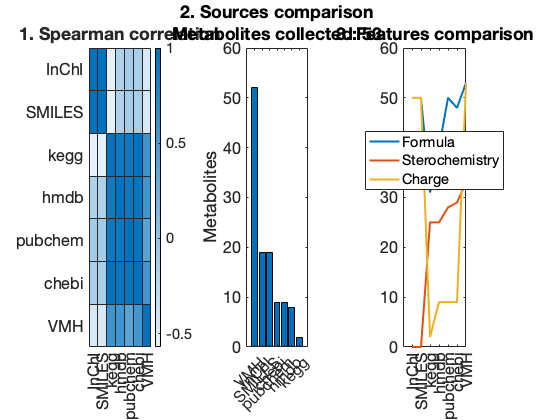

Adjusting pH based on the model's chemical formula ...
 
adjustedpH:
  53×11 table

       mets                       source                     score                                                                                                                                                                        inchi                                                                                                                                                                        chargeOkBool       metFormula       needAdjustmentBool    notPossible2AdjustBool    differentFormula    loopError    pHRangePassed
    __________    _______________________________________    ______    

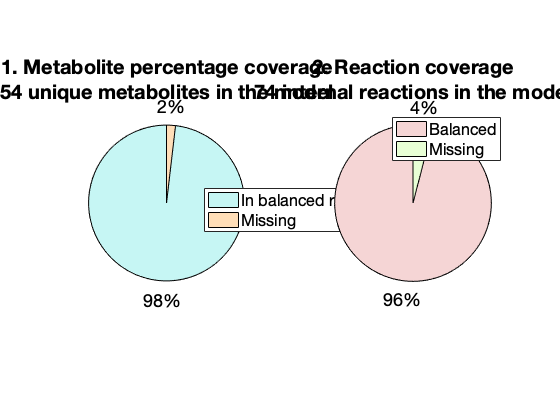

Calculating bonds broken and formed and enthalpy change...
Found biomass reaction: Biomass_Ecoli_core_N(w/GAM)-Nmet2
ATP maintenance reaction is not considered an exchange reaction by default. It should be mass balanced:
ATPM	atp[c] + h2o[c] 	->	adp[c] + h[c] + pi[c] 


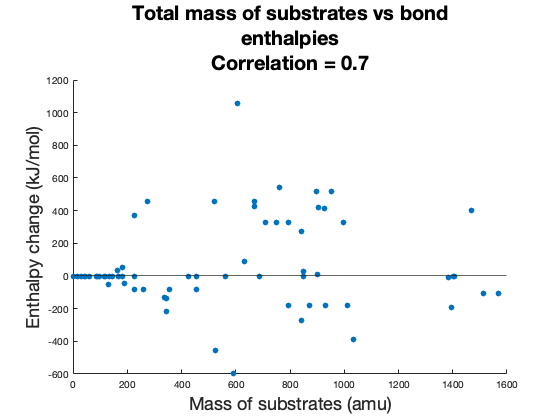

Found biomass reaction: Biomass_Ecoli_core_N(w/GAM)-Nmet2
ATP maintenance reaction is not considered an exchange reaction by default. It should be mass balanced:
ATPM	atp[c] + h2o[c] 	->	adp[c] + h[c] + pi[c] 


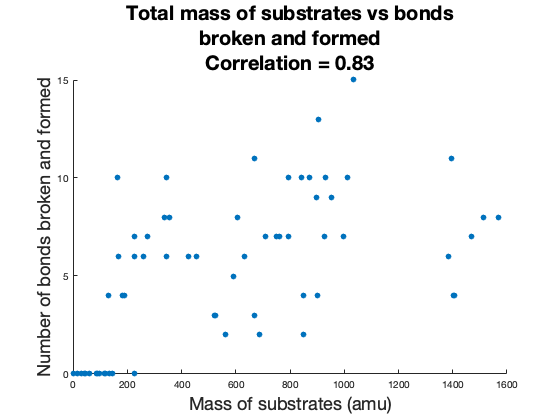

  95×5 table

                    rxns                                                      rxnNames                                       bondsBrokenAndFormed            enthalpyChange          substrateMass
    _____________________________________    __________________________________________________________________________    _________________________    _________________________    _____________

    {'GLUSy'                            }    {'glutamate synthase (NADPH)'                                            }    {' 15'                  }    {'-386'                 }       1032.6    
    {'GLUDy'                            }    {'glutamate dehydrogenase (NADP)'                                        }    {' 13'                  }    {' 421'         

info = generateChemicalDatabase(model, options);

Finally, the function `metDatabaseStatus` is used to check the  consistency of the metabolites in a database in relation to a COBRA model, as well as, showing the type of identifiers in the model.

metDir = [options.outputDir filesep 'mets' filesep 'molFiles'];
[summary, status] = metDatabaseStatus(model, metDir)

summary = struct with fields:
                            mets: 54
                      consistent: 53
             inconsistentFormula: 0
              inconsistentCharge: 0
    inconsistentChargeAndFormula: 0
                         missing: 1
                        inchiIds: 50
                       smilesIds: 50
                        chebiIds: 49
                         hmdbIds: 51
                         keggIds: 50
                      pubchemIds: 50


status = 54×13 table
      met          status       noOfIds      modelFormula      structureFormula    modelCharge    structureCharge    inchiBool    smilesBool    chebiBool    hmdbBool    pubchemBool    keggBool
    ________    ____________    _______    ________________    ________________    ___________    _______________    _________    __________    _________    ________    ___________    ________

    "13dpg"     "consistent"       5       "C3H4O10P2"         "C3H4O10P2"             -4                -4            true         true          fals

## Bibliography

- Dalby et al., "Description of several chemical structure file formats used by computer programs developed at molecular design limited", **(2002).**

- Anderson et al., "Smiles: A line notation and computerized interpreter for chemical structures", *Environmental research Brief* **(1987)**.

- Helle et al., "Inchi, the iupac international chemical identifier", *Journal of Cheminformatics* **(2015)**.

- Noronha et al., "The Virtual Metabolic Human database: integrating human and gut microbiome metabolism with nutrition and disease", *Nucleic acids research*  **(2018).**

- Wishart et al., "HMDB 4.0 — The Human Metabolome Database for 2018_"._ *Nucleic acids research* **(2018).**

- Sunghwan et al. “PubChem in 2021: new data content and improved web interfaces.”  *Nucleic acids research* **(2021).**

- Kanehisa, and Goto. "KEGG: Kyoto Encyclopedia of Genes and Genomes". *Nucleic acids research* **(2000).**

- Hastings et al,. "ChEBI in 2016: Improved services and an expanding collection of metabolites". *Nucleic acids research* **(2016).**

- O'Boyle et al,. "Open Babel: An open chemical toolbox." *Journal of Cheminformatics*  **(2011).**

- "Marvin was used for drawing, displaying and characterizing chemical structures, substructures and reactions, ChemAxon ([<http://www.chemaxon.com](http://www.chemaxon.com/)>)"

- Rahman et al,. "Reaction Decoder Tool (RDT): Extracting Features from Chemical Reactions", Bioinformatics **(2016).**

- Preciat et al., "Comparative evaluation of atom mapping algorithms for balanced metabolic reactions: application to Recon3d", *Journal of Cheminformatics* **(2017)**.